%% ── ROTARY ───────────────────────────────────────────────────────────────────
sets_rot = {'ABC_set1', 'ABC_set2', 'ABC_set3'};
pct_values_rot = 0:5:100;

n_pct_rot = numel(pct_values_rot);
n_set_rot = numel(sets_rot);

avg_A_rot = zeros(n_pct_rot, n_set_rot);
avg_B_rot = zeros(n_pct_rot, n_set_rot);
avg_C_rot = zeros(n_pct_rot, n_set_rot);

base_path_rot = fullfile('Data', 'Rotary_poten');

for s = 1:n_set_rot
    for p = 1:n_pct_rot
        pct = pct_values_rot(p);
        folder = fullfile(base_path_rot, sets_rot{s});
        pattern = sprintf('PotenData_%dPct_*.csv', pct);
        files = dir(fullfile(folder, pattern));

        if isempty(files)
            warning('Rotary Missing: %s / %s', sets_rot{s}, pattern);
            continue;
        end

        fpath = fullfile(files(1).folder, files(1).name);
        T = readtable(fpath, 'VariableNamingRule', 'preserve');

        avg_A_rot(p, s) = mean(T.v_raw_A, 'omitnan');
        avg_B_rot(p, s) = mean(T.v_raw_B, 'omitnan');
        avg_C_rot(p, s) = mean(T.v_raw_C, 'omitnan');
    end
end

% Round
avg_A_rot = round(avg_A_rot, 4);
avg_B_rot = round(avg_B_rot, 4);
avg_C_rot = round(avg_C_rot, 4);

%% ── LINEAR ───────────────────────────────────────────────────────────────────
sets_lin = {'Linear_AB_set1', 'Linear_AB_set2', 'Linear_AB_set3'};
pct_values_lin = 0:5:100;

n_pct_lin = numel(pct_values_lin);
n_set_lin = numel(sets_lin);

avg_A_lin = zeros(n_pct_lin, n_set_lin);
avg_B_lin = zeros(n_pct_lin, n_set_lin);

base_path_lin = fullfile('Data', 'Linear_poten');

for s = 1:n_set_lin
    for p = 1:n_pct_lin
        pct = pct_values_lin(p);
        folder = fullfile(base_path_lin, sets_lin{s});
        pattern = sprintf('PotenData_%dPct_*.csv', pct);
        files = dir(fullfile(folder, pattern));

        if isempty(files)
            warning('Linear Missing: %s / %s', sets_lin{s}, pattern);
            continue;
        end

        fpath = fullfile(files(1).folder, files(1).name);
        T = readtable(fpath, 'VariableNamingRule', 'preserve');

        avg_A_lin(p, s) = mean(T.v_raw_A, 'omitnan');
        avg_B_lin(p, s) = mean(T.v_raw_B, 'omitnan');
    end
end

% Round
avg_A_lin = round(avg_A_lin, 4);
avg_B_lin = round(avg_B_lin, 4);

%% ── PRINT ────────────────────────────────────────────────────────────────────
out = sprintf('=== ROTARY POTENTIOMETER ===\n');
out = [out, sprintf('Pct\t\t| VA_s1\t\tVA_s2\t\tVA_s3\t\t| VB_s1\t\tVB_s2\t\tVB_s3\t\t| VC_s1\t\tVC_s2\t\tVC_s3\n')];
out = [out, sprintf('%s\n', repmat('-', 1, 115))];
for p = 1:n_pct_rot
    out = [out, sprintf('%d%%\t\t| %.4f\t\t%.4f\t\t%.4f\t\t| %.4f\t\t%.4f\t\t%.4f\t\t| %.4f\t\t%.4f\t\t%.4f\n', ...
        pct_values_rot(p), ...
        avg_A_rot(p,1), avg_A_rot(p,2), avg_A_rot(p,3), ...
        avg_B_rot(p,1), avg_B_rot(p,2), avg_B_rot(p,3), ...
        avg_C_rot(p,1), avg_C_rot(p,2), avg_C_rot(p,3))];
end

out = [out, sprintf('\n=== LINEAR POTENTIOMETER ===\n')];
out = [out, sprintf('Pct\t\t| VA_s1\t\tVA_s2\t\tVA_s3\t\t| VB_s1\t\tVB_s2\t\tVB_s3\n')];
out = [out, sprintf('%s\n', repmat('-', 1, 80))];
for p = 1:n_pct_lin
    out = [out, sprintf('%d%%\t\t| %.4f\t\t%.4f\t\t%.4f\t\t| %.4f\t\t%.4f\t\t%.4f\n', ...
        pct_values_lin(p), ...
        avg_A_lin(p,1), avg_A_lin(p,2), avg_A_lin(p,3), ...
        avg_B_lin(p,1), avg_B_lin(p,2), avg_B_lin(p,3))];
end

disp(out);

=== ROTARY POTENTIOMETER ===
Pct		| VA_s1		VA_s2		VA_s3		| VB_s1		VB_s2		VB_s3		| VC_s1		VC_s2		VC_s3
-------------------------------------------------------------------------------------------------------------------
0%		| 0.0000		0.0000		0.0289		| 0.0000		0.0000		0.0288		| 0.0000		0.0000		0.0288
5%		| 0.0000		0.0000		0.0000		| 0.0000		0.0000		0.0000		| 0.0000		0.0000		0.0000
10%		| 0.0000		0.0000		0.0000		| 0.0000		0.0000		0.0000		| 0.2499		0.2777		0.2629
15%		| 0.0000		0.0027		0.0009		| 0.1130		0.1515		0.1508		| 0.6791		0.7884		0.7113
20%		| 0.0291		0.0363		0.0371		| 0.3320		0.3264		0.3367		| 1.0476		1.0965		1.1624
25%		| 0.0743		0.0815		0.0801		| 0.5273		0.5017		0.5070		| 1.6646		1.5976		1.6562
30%		| 0.1150		0.1192		0.1158		| 0.7649		0.6813		0.6756		| 2.0851		2.0171		2.0353
35%		| 0.1585		0.1608		0.1559		| 0.9293		0.8925		0.8796		| 2.5113		2.5083		2.4827
40%		| 0.1946		0.1977		0.1974		| 1.1272		1.0526		1.0377		| 2.7662		2.7680		2.7683
45%		| 0.2388		0.2372		0.2319		| 1.3150		1.264


%% ── SAVE CSV ─────────────────────────────────────────────────────────────────
pct_rot_str = arrayfun(@(x) sprintf('%d%%', x), pct_values_rot', 'UniformOutput', false);
rotary_result = table(pct_rot_str, ...
    avg_A_rot(:,1), avg_A_rot(:,2), avg_A_rot(:,3), ...
    avg_B_rot(:,1), avg_B_rot(:,2), avg_B_rot(:,3), ...
    avg_C_rot(:,1), avg_C_rot(:,2), avg_C_rot(:,3), ...
    'VariableNames', {'Pct', ...
        'VA_set1','VA_set2','VA_set3', ...
        'VB_set1','VB_set2','VB_set3', ...
        'VC_set1','VC_set2','VC_set3'});
writetable(rotary_result, 'summary_rotary.csv');

pct_lin_str = arrayfun(@(x) sprintf('%d%%', x), pct_values_lin', 'UniformOutput', false);
linear_result = table(pct_lin_str, ...
    avg_A_lin(:,1), avg_A_lin(:,2), avg_A_lin(:,3), ...
    avg_B_lin(:,1), avg_B_lin(:,2), avg_B_lin(:,3), ...
    'VariableNames', {'Pct', ...
        'VA_set1','VA_set2','VA_set3', ...
        'VB_set1','VB_set2','VB_set3'});
writetable(linear_result, 'summary_linear.csv');

fprintf('Saved: summary_rotary.csv and summary_linear.csv\n');

Saved: summary_rotary.csv and summary_linear.csv


 Plot

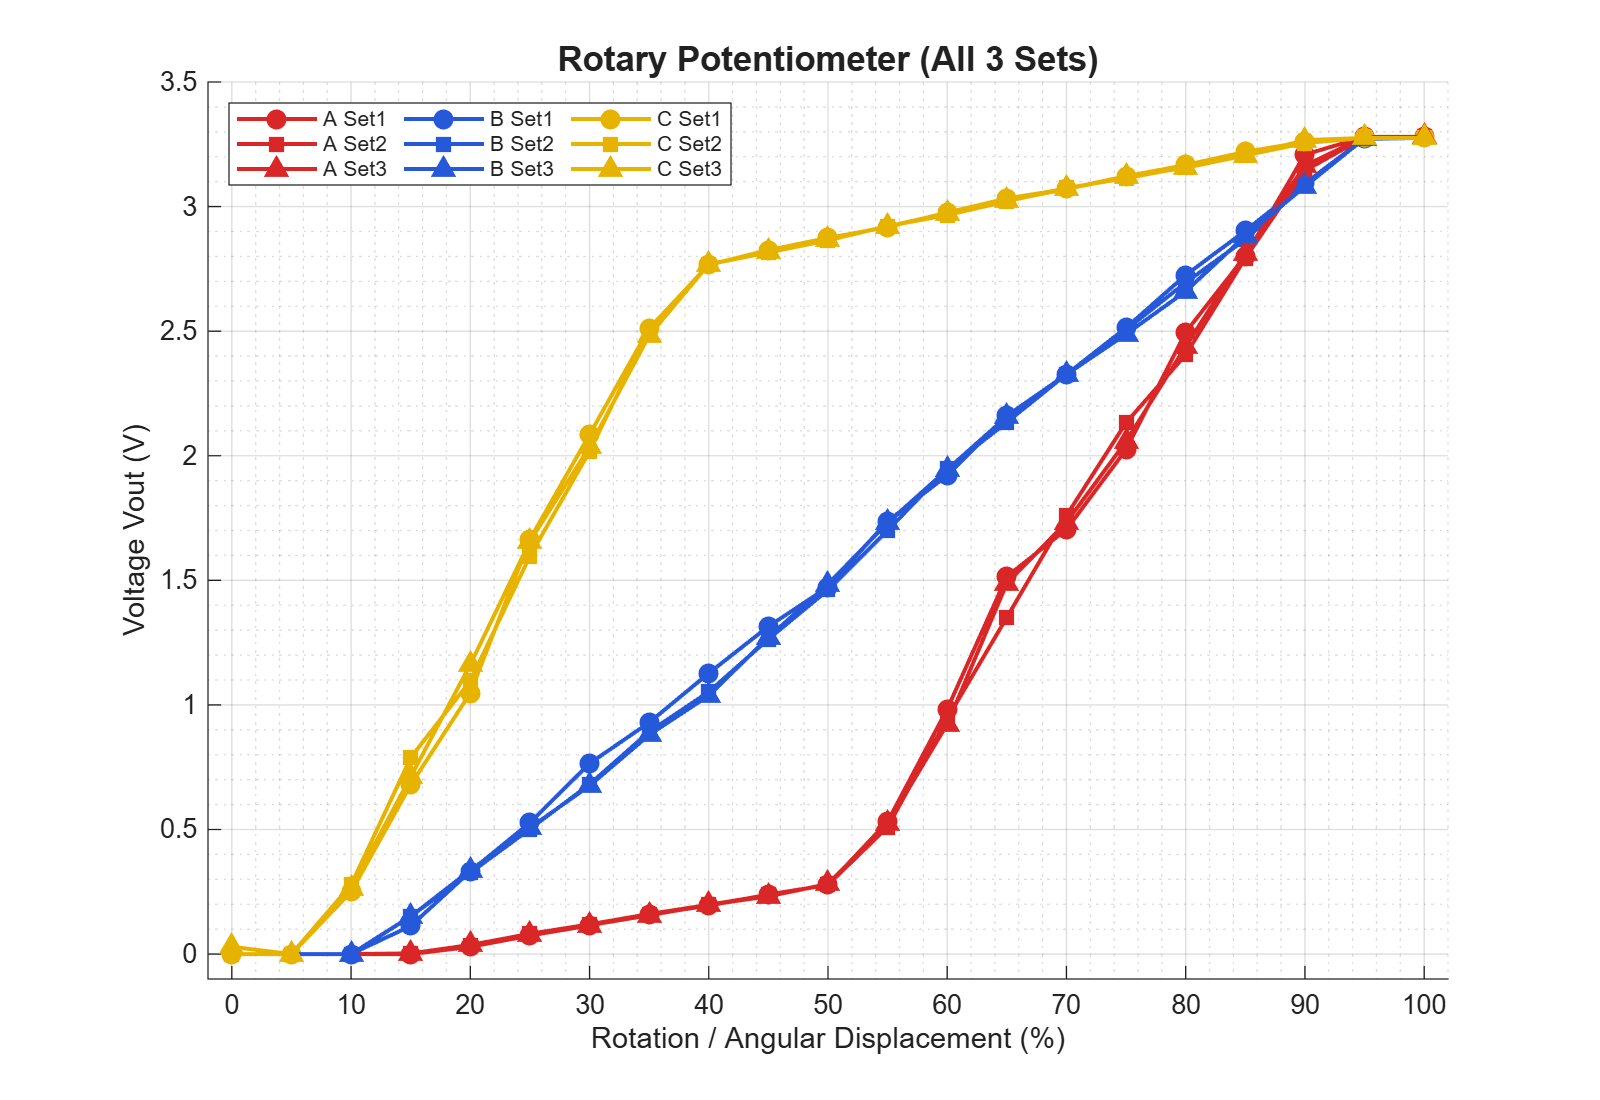

%% ── PLOT 1: Rotary — All sets combined, A/B/C by color ──────────────────────
figure('Name','Rotary - All Sets','Position',[100 100 800 550]);

pct = pct_values_rot;

% Markers per set: circle, square, triangle
markers = {'o','s','^'};
ms = 6; lw = 1.5;

% Colors: A=red, B=blue, C=yellow(gold)
col_A = [0.85 0.15 0.15];
col_B = [0.15 0.35 0.85];
col_C = [0.90 0.70 0.00];

hold on;
for s = 1:3
    h_A(s) = plot(pct, avg_A_rot(:,s), markers{s}, 'Color',col_A, 'MarkerFaceColor',col_A, 'MarkerSize',ms, 'LineWidth',lw, 'LineStyle','-');
    h_B(s) = plot(pct, avg_B_rot(:,s), markers{s}, 'Color',col_B, 'MarkerFaceColor',col_B, 'MarkerSize',ms, 'LineWidth',lw, 'LineStyle','-');
    h_C(s) = plot(pct, avg_C_rot(:,s), markers{s}, 'Color',col_C, 'MarkerFaceColor',col_C, 'MarkerSize',ms, 'LineWidth',lw, 'LineStyle','-');
end
hold off;

xlabel('Rotation / Angular Displacement (%)', 'FontSize',11);
ylabel('Voltage Vout (V)', 'FontSize',11);
title('Rotary Potentiometer (All 3 Sets)', 'FontSize',13, 'FontWeight','bold');
xlim([-2 102]); ylim([-0.1 3.5]);
xticks(0:10:100); yticks(0:0.5:3.5);
grid on; grid minor;

legend([h_A(1) h_A(2) h_A(3) h_B(1) h_B(2) h_B(3) h_C(1) h_C(2) h_C(3)], ...
    {'A Set1','A Set2','A Set3','B Set1','B Set2','B Set3','C Set1','C Set2','C Set3'}, ...
    'Location','northwest', 'NumColumns',3, 'FontSize',8);

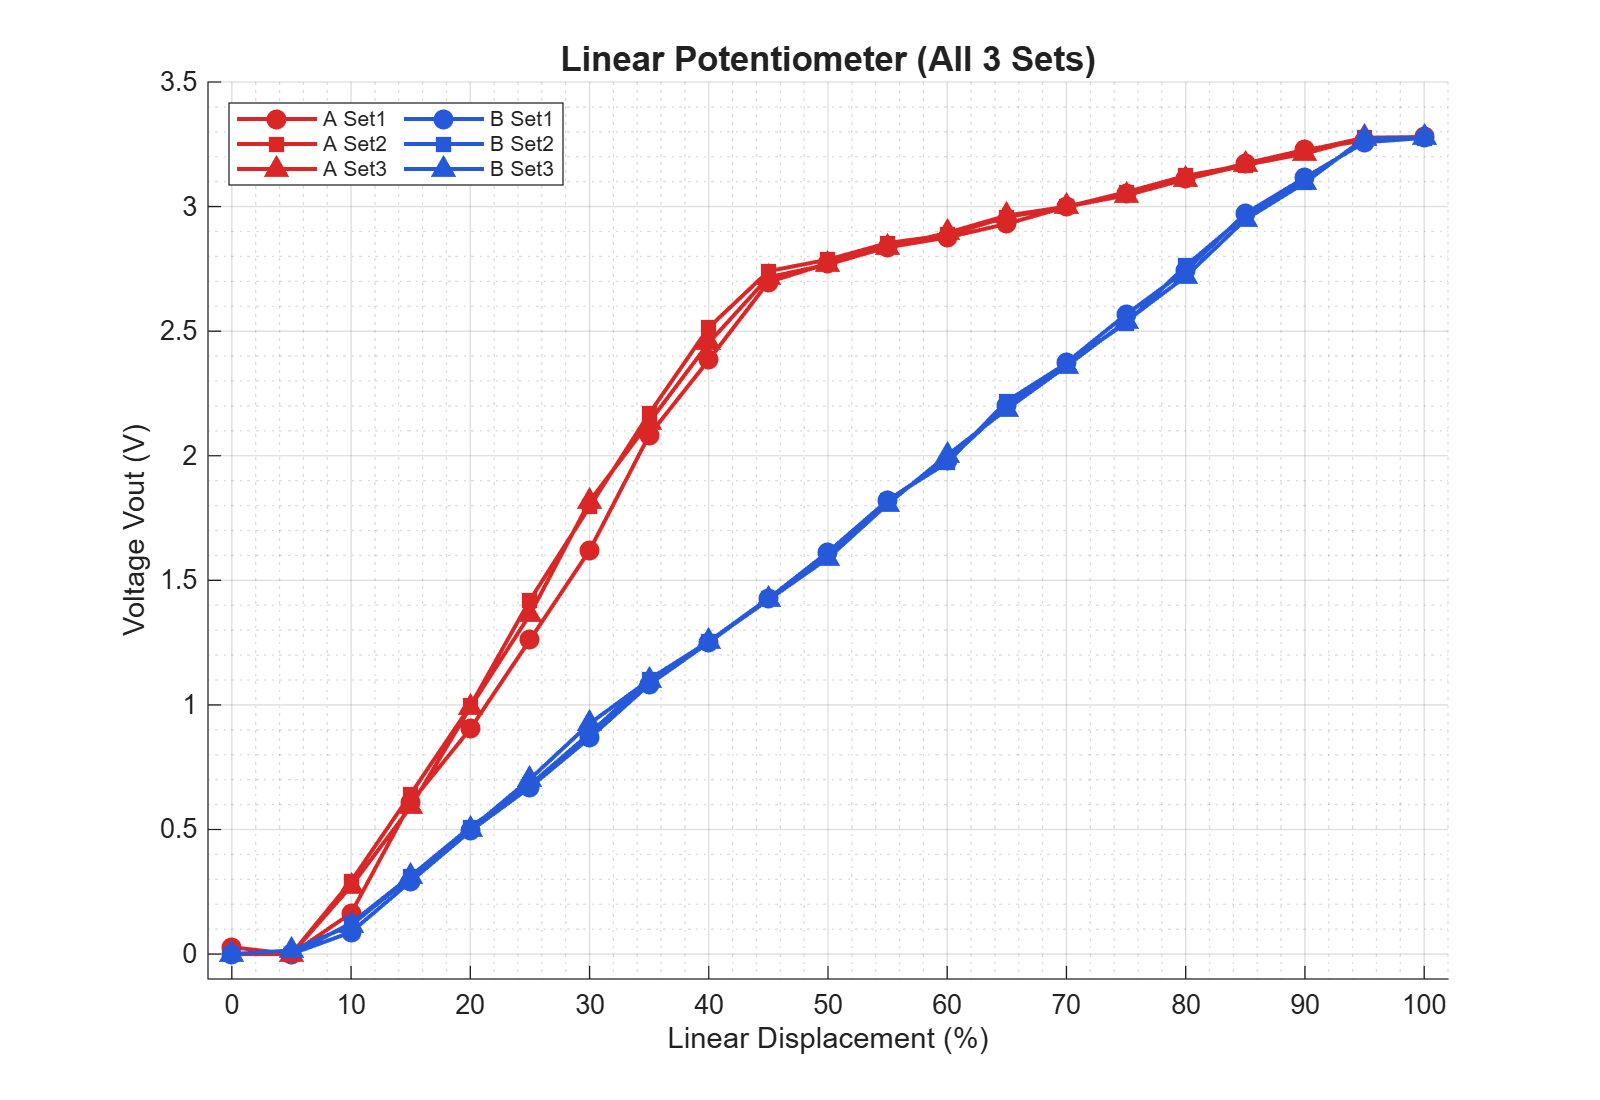


%% ── PLOT 2: Linear — All sets combined, A/B by color ────────────────────────
figure('Name','Linear - All Sets','Position',[100 100 800 550]);

pct = pct_values_lin;

hold on;
for s = 1:3
    h_A(s) = plot(pct, avg_A_lin(:,s), markers{s}, 'Color',col_A, 'MarkerFaceColor',col_A, 'MarkerSize',ms, 'LineWidth',lw, 'LineStyle','-');
    h_B(s) = plot(pct, avg_B_lin(:,s), markers{s}, 'Color',col_B, 'MarkerFaceColor',col_B, 'MarkerSize',ms, 'LineWidth',lw, 'LineStyle','-');
end
hold off;

xlabel('Linear Displacement (%)', 'FontSize',11);
ylabel('Voltage Vout (V)', 'FontSize',11);
title('Linear Potentiometer (All 3 Sets)', 'FontSize',13, 'FontWeight','bold');
xlim([-2 102]); ylim([-0.1 3.5]);
xticks(0:10:100); yticks(0:0.5:3.5);
grid on; grid minor;

legend([h_A(1) h_A(2) h_A(3) h_B(1) h_B(2) h_B(3)], ...
    {'A Set1','A Set2','A Set3','B Set1','B Set2','B Set3'}, ...
    'Location','northwest', 'NumColumns',2, 'FontSize',8);

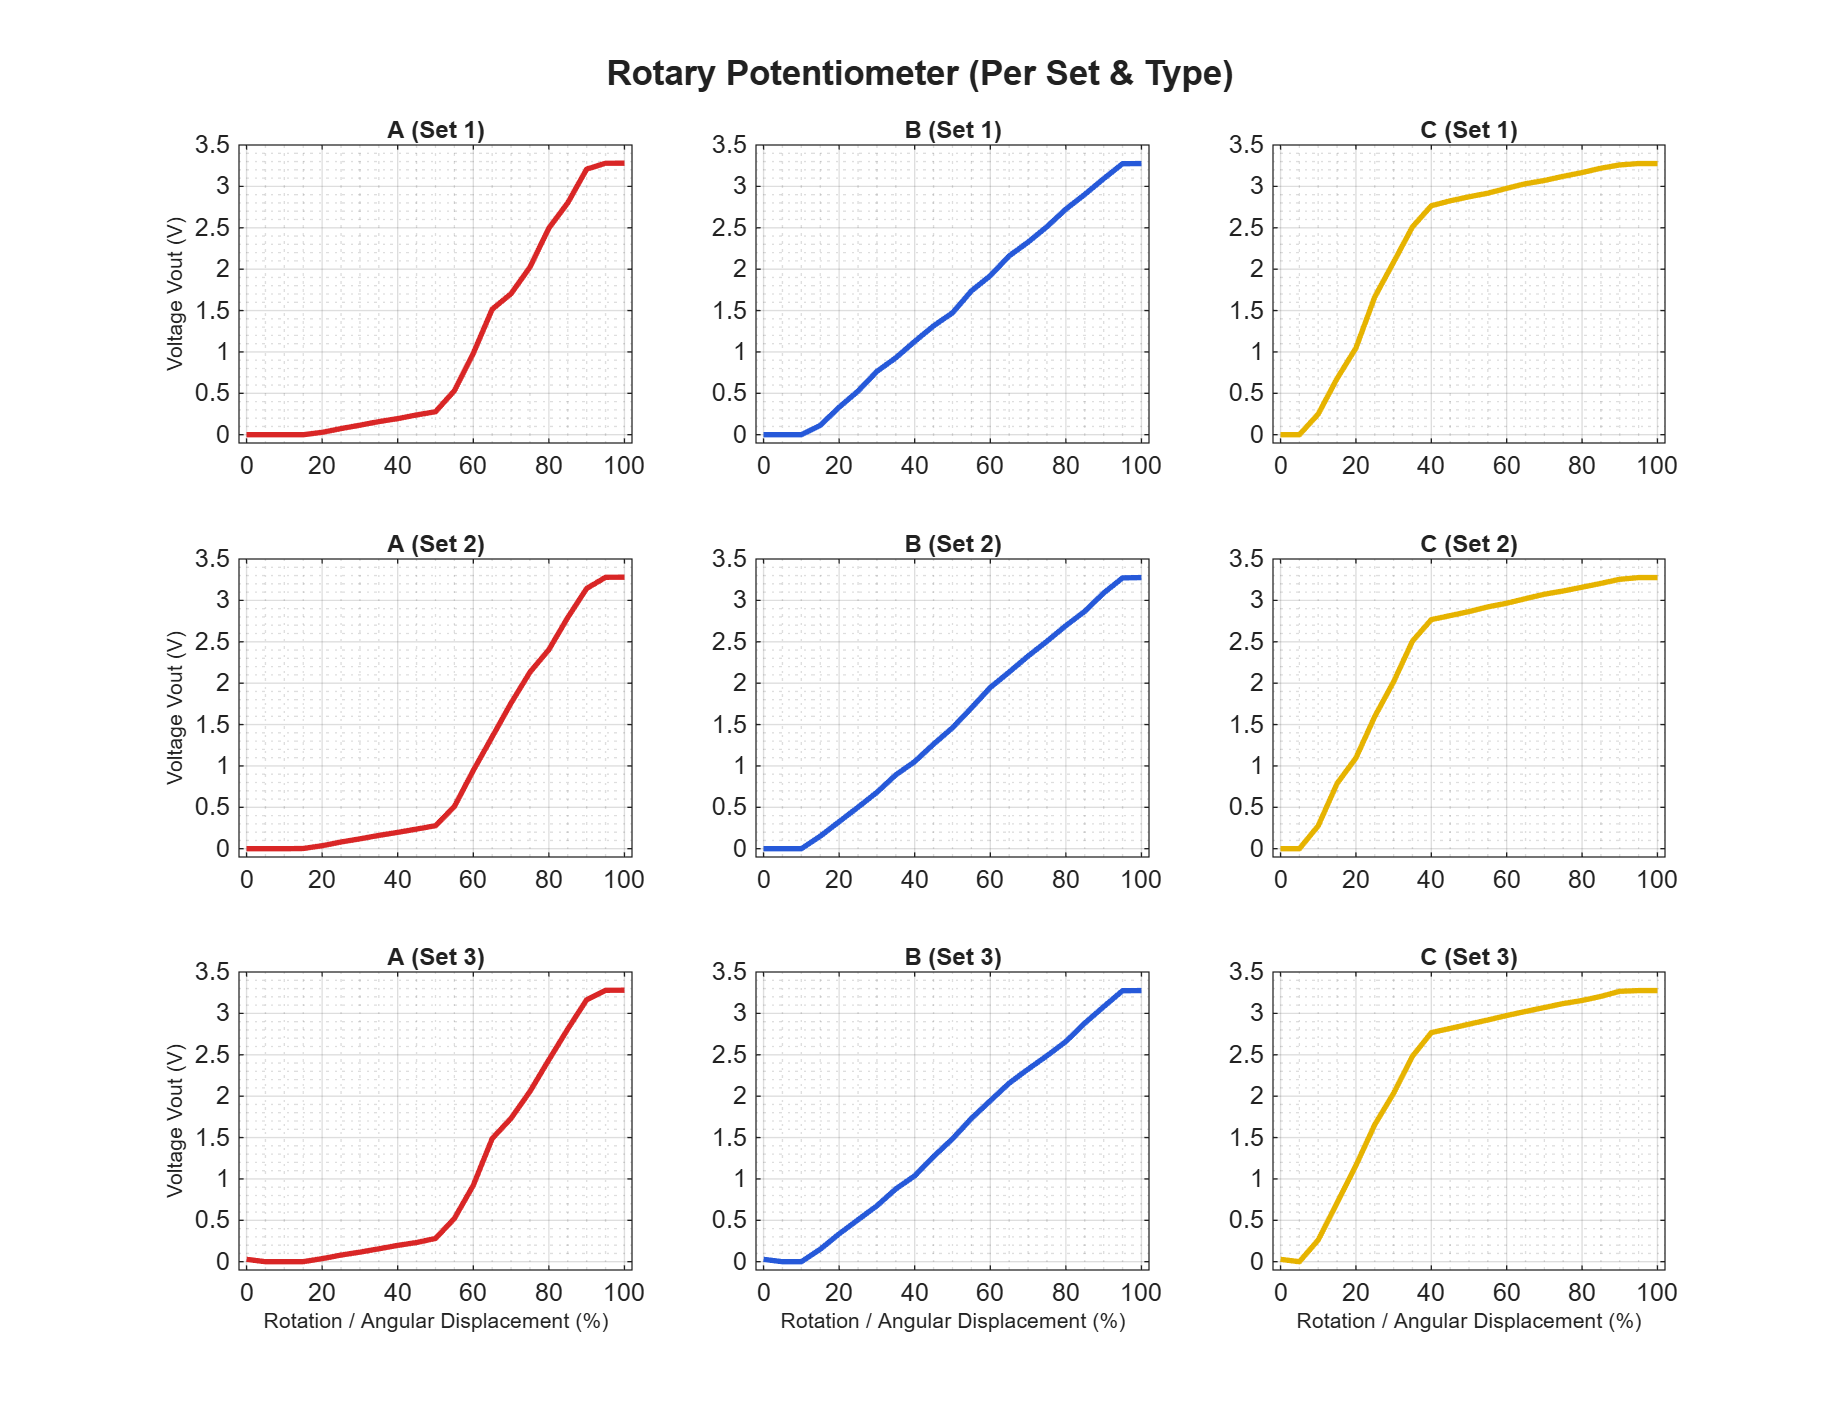


%% ── PLOT 3: Rotary — 3x3 (row=set, col=channel) ────────────────────────────
figure('Name','Rotary 3x3','Position',[100 100 1100 850]);

channels    = {avg_A_rot, avg_B_rot, avg_C_rot};
chan_labels  = {'A', 'B', 'C'};
chan_colors  = {col_A, col_B, col_C};
set_labels   = {'Set 1','Set 2','Set 3'};
pct = pct_values_rot;

for r = 1:3        % set (row)
    for c = 1:3    % channel (col)
        subplot(3, 3, (r-1)*3 + c);
        data = channels{c};
        plot(pct, data(:,r), '-', ...
            'Color', chan_colors{c}, ...
            'LineWidth', 2.0);
        title(sprintf('%s (%s)', chan_labels{c}, set_labels{r}), 'FontSize', 9);
        if r == 3, xlabel('Rotation / Angular Displacement (%)', 'FontSize', 8); end
        if c == 1, ylabel('Voltage Vout (V)', 'FontSize', 8); end
        xlim([-2 102]); ylim([-0.1 3.5]);
        xticks(0:20:100); yticks(0:0.5:3.5);
        grid on; grid minor;
    end
end
sgtitle('Rotary Potentiometer (Per Set & Type)', 'FontSize', 13, 'FontWeight', 'bold');

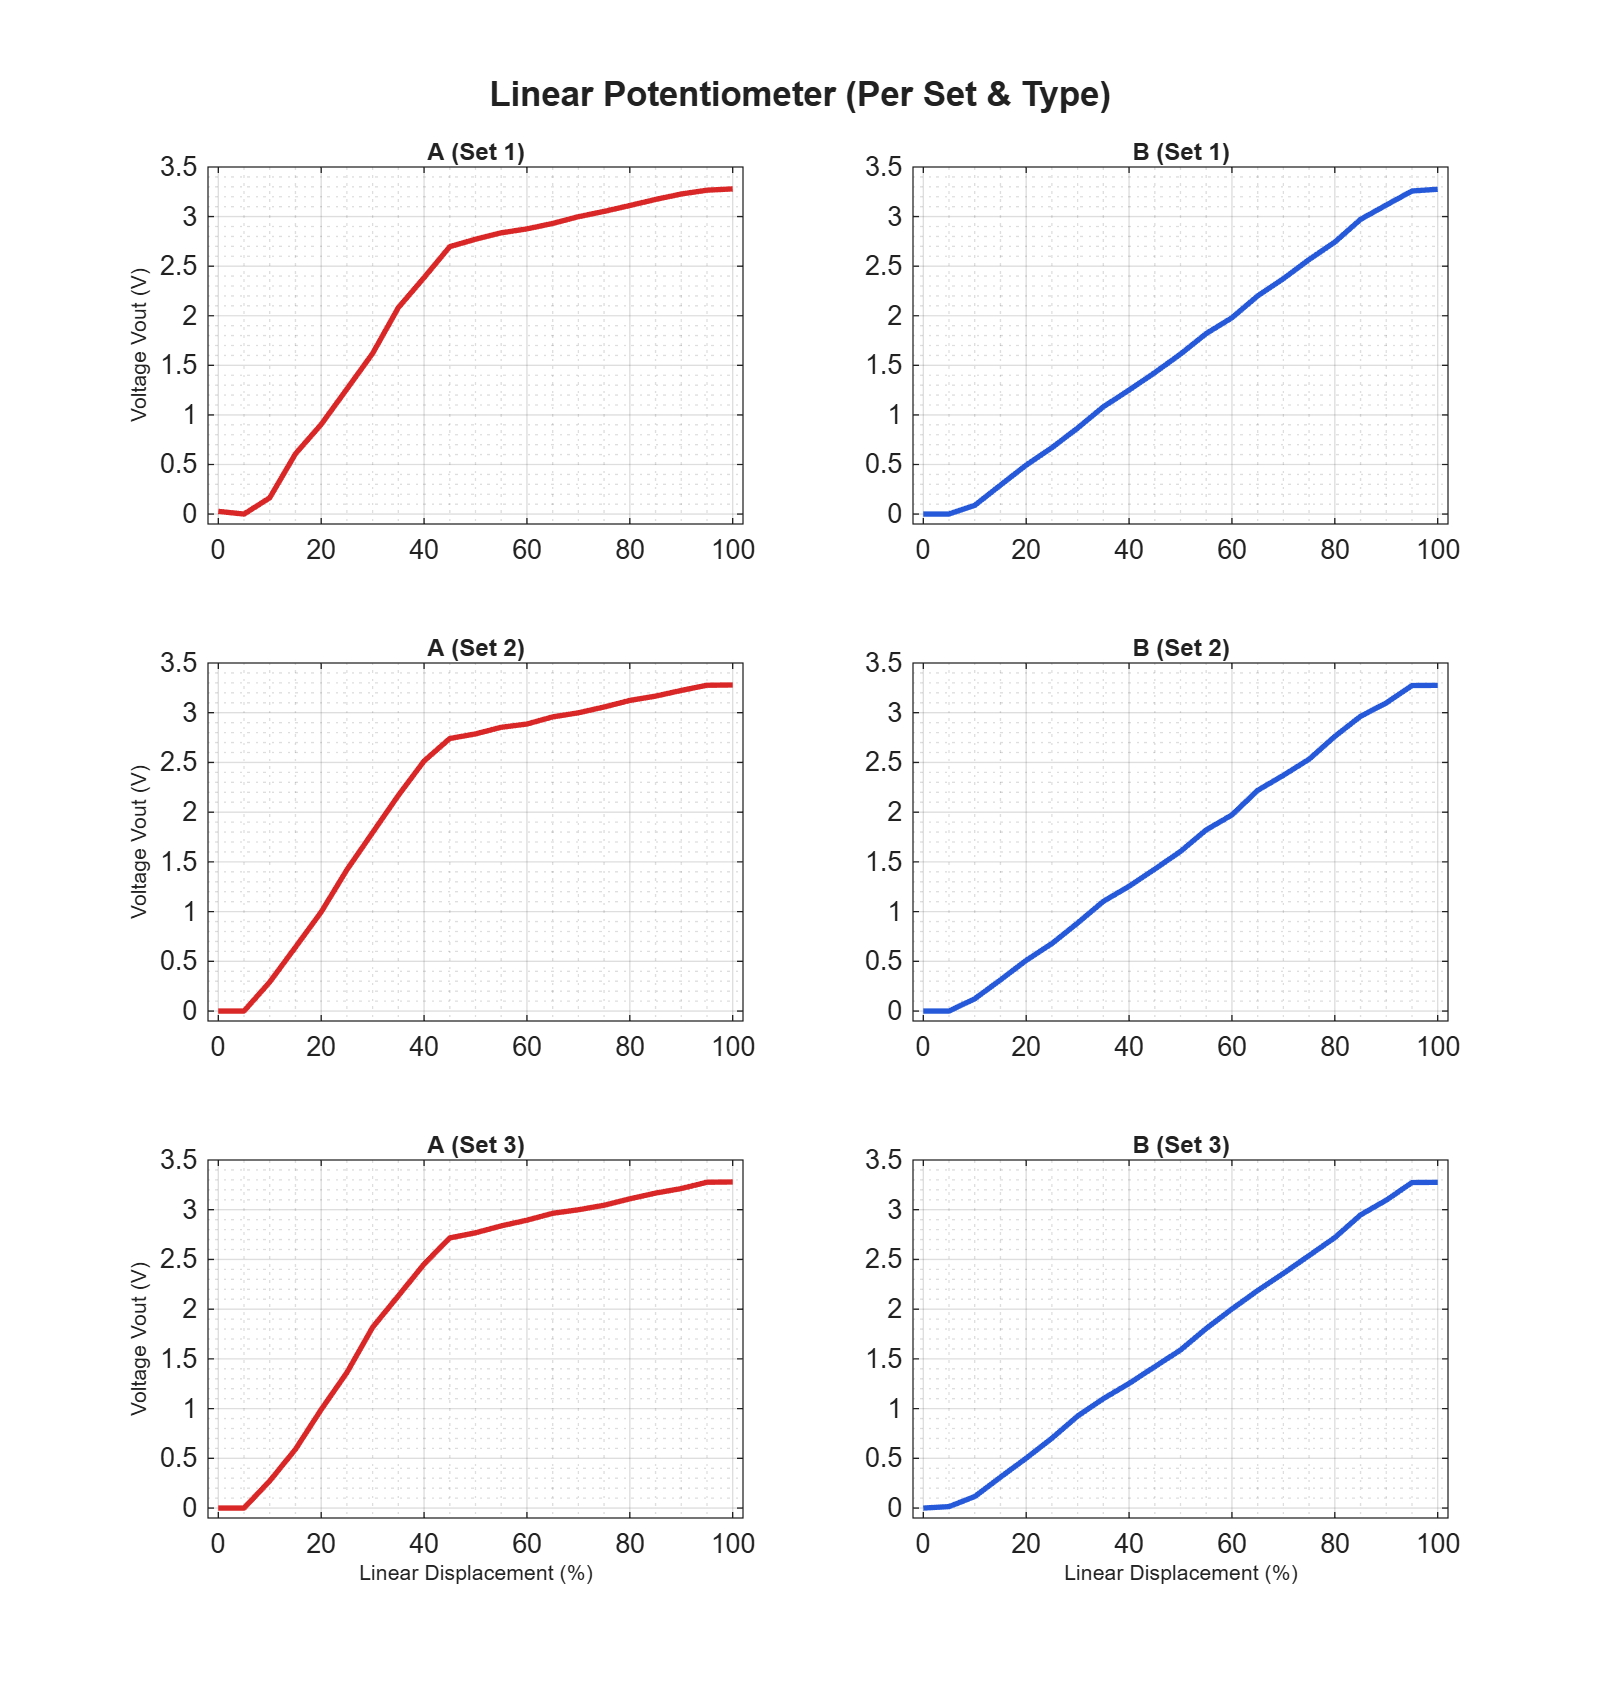


%% ── PLOT 4: Linear — 3x2 (row=set, col=channel) ────────────────────────────
figure('Name','Linear 3x2','Position',[100 100 800 850]);

channels_lin   = {avg_A_lin, avg_B_lin};
chan_labels_lin = {'A', 'B'};
chan_colors_lin = {col_A, col_B};
pct = pct_values_lin;

for r = 1:3        % set (row)
    for c = 1:2    % channel (col)
        subplot(3, 2, (r-1)*2 + c);
        data = channels_lin{c};
        plot(pct, data(:,r), '-', ...
            'Color', chan_colors_lin{c}, ...
            'LineWidth', 2.0);
        title(sprintf('%s (%s)', chan_labels_lin{c}, set_labels{r}), 'FontSize', 9);
        if r == 3, xlabel('Linear Displacement (%)', 'FontSize', 8); end
        if c == 1, ylabel('Voltage Vout (V)', 'FontSize', 8); end
        xlim([-2 102]); ylim([-0.1 3.5]);
        xticks(0:20:100); yticks(0:0.5:3.5);
        grid on; grid minor;
    end
end
sgtitle('Linear Potentiometer (Per Set & Type)', 'FontSize', 13, 'FontWeight', 'bold');

Vcc = 3.3;
pct_col = pct_values_rot';

V_theoretical = round((pct_col / 100) * Vcc, 4);
avg_B_rot_all = round(mean(avg_B_rot, 2), 4);
avg_B_lin_all = round(mean(avg_B_lin, 2), 4);
ae_rot        = round(abs(avg_B_rot_all - V_theoretical), 4);
ae_lin        = round(abs(avg_B_lin_all - V_theoretical), 4);
mae_rot       = round(mean(ae_rot), 4);
mae_lin       = round(mean(ae_lin), 4);

pct_str      = arrayfun(@(x) sprintf('%d%%',  x), pct_col,       'UniformOutput', false);
rot_exp_str  = arrayfun(@(x) sprintf('%.4f',  x), avg_B_rot_all, 'UniformOutput', false);
rot_calc_str = arrayfun(@(x) sprintf('%.4f',  x), V_theoretical, 'UniformOutput', false);
rot_ae_str   = arrayfun(@(x) sprintf('%.4f',  x), ae_rot,        'UniformOutput', false);
lin_exp_str  = arrayfun(@(x) sprintf('%.4f',  x), avg_B_lin_all, 'UniformOutput', false);
lin_calc_str = arrayfun(@(x) sprintf('%.4f',  x), V_theoretical, 'UniformOutput', false);
lin_ae_str   = arrayfun(@(x) sprintf('%.4f',  x), ae_lin,        'UniformOutput', false);

comp_result = table(pct_str, ...
    rot_exp_str, rot_calc_str, rot_ae_str, ...
    lin_exp_str, lin_calc_str, lin_ae_str, ...
    'VariableNames', {'Pct', ...
    'Rotary_B_Exp','Rotary_B_Calc','Rotary_AE', ...
    'Linear_B_Exp','Linear_B_Calc','Linear_AE'});

mae_row = table({'MAE'}, {''}, {''}, {sprintf('%.4f', mae_rot)}, ...
    {''}, {''}, {sprintf('%.4f', mae_lin)}, ...
    'VariableNames', comp_result.Properties.VariableNames);

comp_result = [comp_result; mae_row];
writetable(comp_result, 'summary_comparison.txt', 'Delimiter', '\t', 'QuoteStrings', false);
fprintf('MAE — Rotary: %.4f V  |  Linear: %.4f V\n', mae_rot, mae_lin);

MAE — Rotary: 0.1554 V  |  Linear: 0.0926 V
